# Assignment 2 - Stanford Arm Code - Neal Elharidy

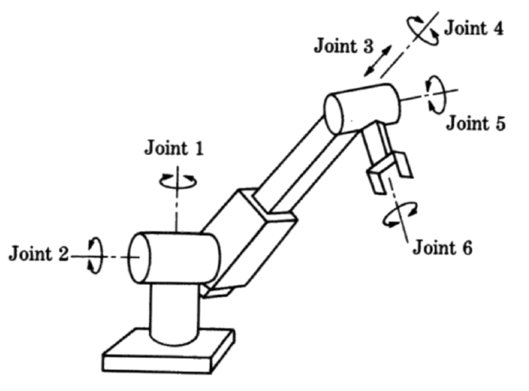

## Initialization

clear all; clc;

% Joint Variables
t1 = pi/4; t2 = pi/4; d3 = 3; t4 = pi/4; t5 = pi/4; t6 = pi/4;
q = [t1; t2; d3; t4; t5; t6];

% Fixed Variables
D2 = 2; D6 = 6;

## Symbolic Variables Linear Jacobian

sym_lin_jac(q,D2,D6);

The Linear Jacobian: 


The Linear Jacobian Value is: 
   -8.6569    2.1213    0.5000   -3.6213   -2.7426         0
    1.5858    2.1213    0.5000    0.6213    1.5000         0
         0   -7.2426    0.7071    2.1213   -5.1213         0



## Linear Jacobian Calculation (Q2)

disp(lin_jac(q,D2,D6));

   -8.6569    2.1213    0.5000   -3.6213   -2.7426         0
    1.5858    2.1213    0.5000    0.6213    1.5000         0
         0   -7.2426    0.7071    2.1213   -5.1213         0



## Manipulability Calculation (Q3)

disp(manipulability(q,D2,D6));

  105.7386



## Trajectory Calculation & Plotting Ex#1 (Q4&5)

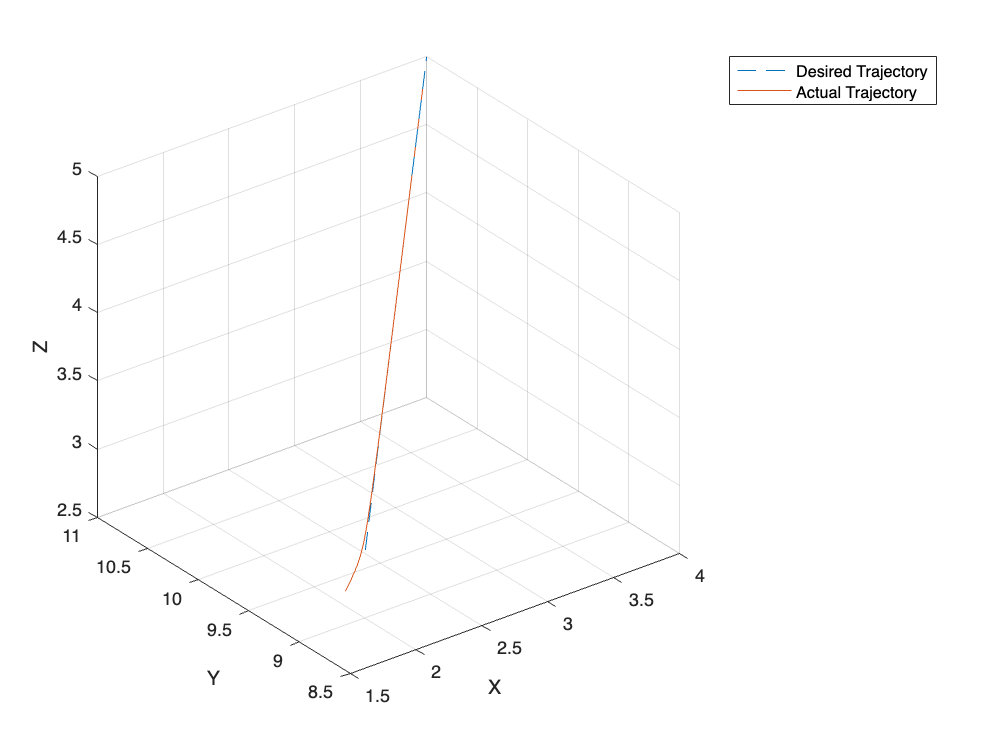

p0 = [2; 9; 3];
pf = [4; 11; 5];
tf = 10;

[qi, p_desired, x, mu] = follow_trajectory(p0,pf,tf,q,D2,D6);

figure;
plot3(p_desired(1,:), p_desired(2,:), p_desired(3,:), '--'); hold on;
plot3(x(1,:), x(2,:), x(3,:)); hold off;
xlabel('X'); ylabel('Y'); zlabel('Z'); grid on;
legend('Desired Trajectory', 'Actual Trajectory');

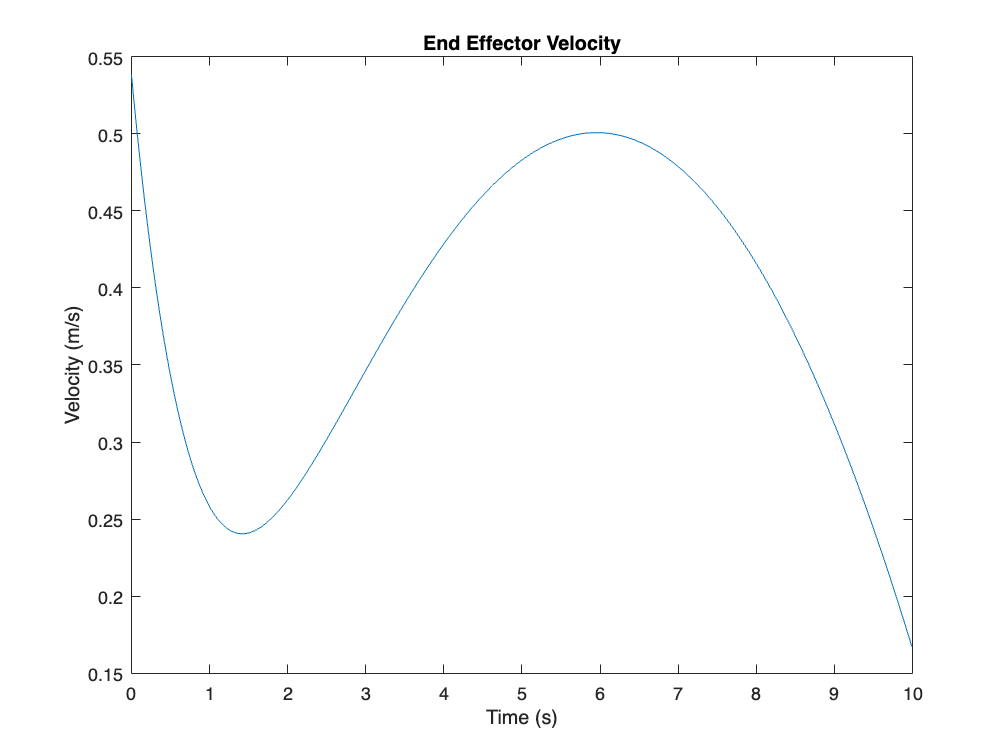

% Plotting axuilary Velocity and Manipulability plots.
v = sqrt(sum(diff(x, 1, 2).^2)) / 0.01;

plot(0:0.01:(tf-0.01), v);
title('End Effector Velocity');
xlabel('Time (s)'); ylabel('Velocity (m/s)');

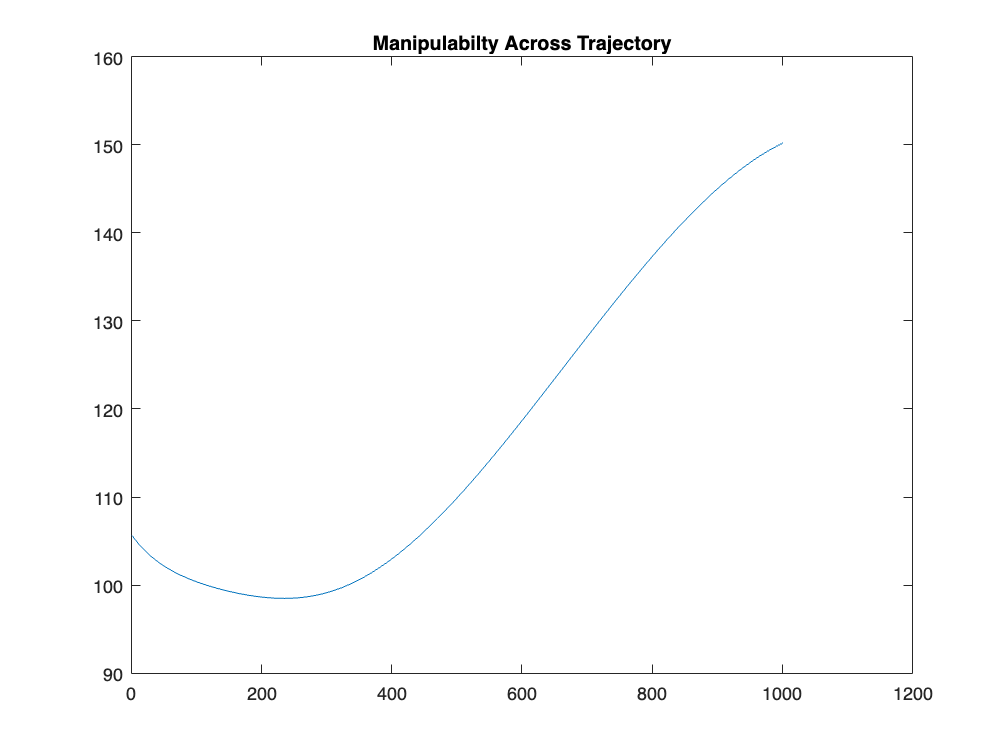

plot(mu); title("Manipulabilty Across Trajectory");

## Trajectory Calculation and Plotting Ex#2

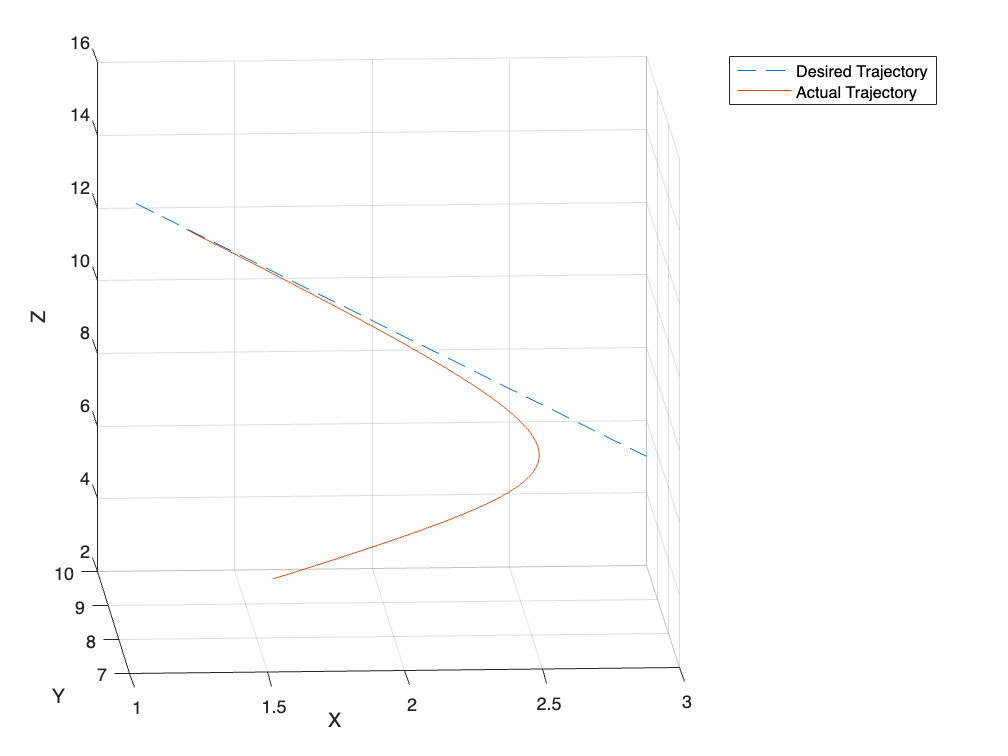

p0 = [3; 10; 5];
pf = [1; 7; 15];
tf = 6;

[qi, p_desired, x, mu] = follow_trajectory(p0,pf,tf,q,D2,D6);

figure;
plot3(p_desired(1,:), p_desired(2,:), p_desired(3,:), '--'); hold on;
plot3(x(1,:), x(2,:), x(3,:)); hold off;
xlabel('X'); ylabel('Y'); zlabel('Z'); grid on; 
legend('Desired Trajectory', 'Actual Trajectory');


% Better View of trajectory
view([-3.4 11.3])

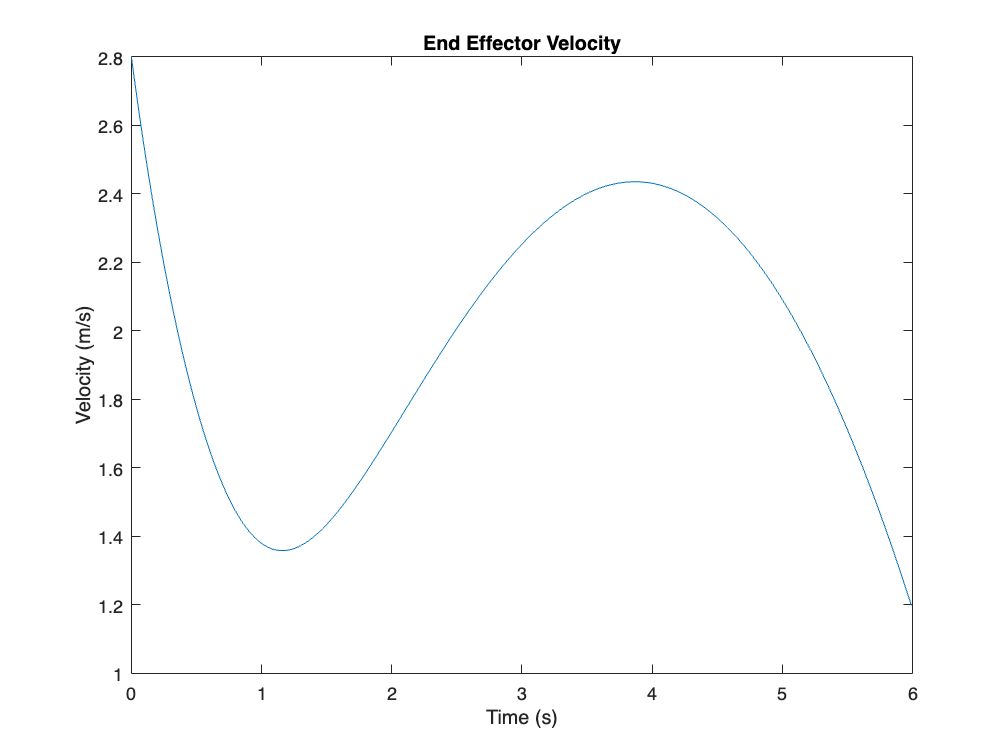

% Plotting axuilary Velocity and Manipulability plots.
v = sqrt(sum(diff(x, 1, 2).^2)) / 0.01;

plot(0:0.01:(tf-0.01), v);
title('End Effector Velocity');
xlabel('Time (s)'); ylabel('Velocity (m/s)');

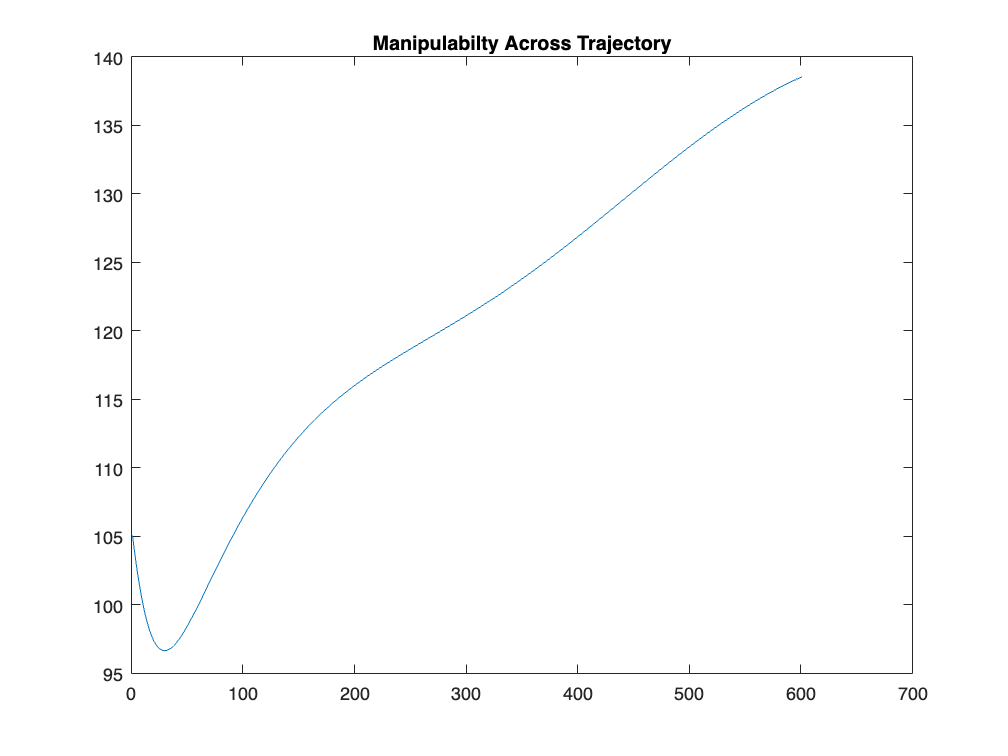

plot(mu); title("Manipulabilty Across Trajectory");